%2
%a
I1=0.1^4/12

I1 = 8.3333e-06

I2=pi/4*0.03^4

I2 = 6.3617e-07

I3=pi/4*0.015^4

I3 = 3.9761e-08

%b
E=200*10^9;
L=5/4;
k=cell(1,16);
for i=1:4
    k{i}=[12*E*I1/L^3 6*E*I1/L^2 -12*E*I1/L^3 6*E*I1/L^2; ...
        6*E*I1/L^2 4*E*I1/L -6*E*I1/L^2 2*E*I1/L; ...
        -12*E*I1/L^3 -6*E*I1/L^2 12*E*I1/L^3 -6*E*I1/L^2; ...
        6*E*I1/L^2 2*E*I1/L -6*E*I1/L^2 4*E*I1/L];
end
for i=5:12
    k{i}=[12*E*I2/L^3 6*E*I2/L^2 -12*E*I2/L^3 6*E*I2/L^2; ...
        6*E*I2/L^2 4*E*I2/L -6*E*I2/L^2 2*E*I2/L; ...
        -12*E*I2/L^3 -6*E*I2/L^2 12*E*I2/L^3 -6*E*I2/L^2; ...
        6*E*I2/L^2 2*E*I2/L -6*E*I2/L^2 4*E*I2/L];
end
for i=12:16
    k{i}=[12*E*I3/L^3 6*E*I3/L^2 -12*E*I3/L^3 6*E*I3/L^2; ...
        6*E*I3/L^2 4*E*I3/L -6*E*I3/L^2 2*E*I3/L; ...
        -12*E*I3/L^3 -6*E*I3/L^2 12*E*I3/L^3 -6*E*I3/L^2; ...
        6*E*I3/L^2 2*E*I3/L -6*E*I3/L^2 4*E*I3/L];
end

kglobal=zeros(34);
for i=1:16
    n=2*i-1;
    kglobal(n:n+1,n:n+1)=kglobal(n:n+1,n:n+1)+k{i}(1:2,1:2);
    kglobal(n:n+1,n+2:n+3)=kglobal(n:n+1,n+2:n+3)+k{i}(1:2,3:4);
    kglobal(n+2:n+3,n:n+1)=kglobal(n+2:n+3,n:n+1)+k{i}(3:4,1:2);
    kglobal(n+2:n+3,n+2:n+3)=kglobal(n+2:n+3,n+2:n+3)+k{i}(3:4,3:4);
end
kreduced=kglobal(3:34,3:34);
kgnorm=norm(kglobal)

kgnorm = 3.8715e+07

krcond=cond(kreduced)

krcond = 1.8950e+06


%c
q=30;
f=zeros(32,1);
f(7)=q*10/2;
f(8)=-q*100/12;
f(23)=q*10/2-100;
f(24)=q*100/12;
f(32)=-2000;
dr=kreduced\f

dr =    -0.0003
   -0.0005
   -0.0012
   -0.0011
   -0.0032
   -0.0020
   -0.0062
   -0.0030
   -0.0178
   -0.0156


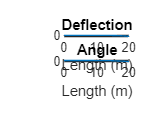


%d&e
length=0:L:20;
deflection=zeros(16,1);
for i=1:16
    n=2*i-1;
    deflection(i)=dr(n);
end
deflection=[0; deflection];
rotation=zeros(16,1);
for i=1:16
    n=2*i;
    rotation(i)=dr(n);
end
rotation=[0; rotation]*180/pi;
tiledlayout(2,1)
nexttile
plot(length,deflection);
title("Deflection")
xlabel("Length (m)")
ylabel("Displacement (m)")
nexttile
plot(length,rotation);
title("Angle")
xlabel("Length (m)")
ylabel("Angle (deg)")


%f
dr=[0;0;dr];
fm=kglobal*dr;
fm(1:2)

ans =  -200.0000
  500.0000
